s0_add_paths;

## Agenda

- Show the fit R square, 

## The fitted parameters of the classic model

% classic parameters 
sig   = 0.0365;
g     = 4.0304;
alpha = Sigmoid(-0.6607);
g_prime = g ^ (1/alpha);
b = sig / g_prime;
w = 1 / g_prime;
opt_param = [w, b, -0.6607]

opt_param =     0.0167    0.0006   -0.6607


## The loss landscape

% parameters
target = 'target'; ds = 2; roi = 1; n = 20;
model = oriSurroundModel(); model_idx = 3;
fit_param = dataloader(stdnormRootPath, 'param', target, ds, roi, 'noCross', model_idx, 'fmincon');
fit_param(2) = 0.0006

fit_param =     0.0714    0.0006   11.9391


wLst = linspace(.01, 0.03, n);
aLst = linspace(0, 1, n);
mse_land = nan(n, n);

% input 
E = dataloader(stdnormRootPath, 'E_xy', target, ds, roi);
Z = dataloader(stdnormRootPath, 'Z1', target, ds, roi);

% output 
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target', target, ds, roi); 


for i = 1:n
    for j = 1:n
        subplot(n, n, n*(i-1)+j)
        fit_param(1) = wLst(i);
        opt_param(3) = aLst(j);
        BOLD_hat = model.forward(model, {E, Z}, fit_param);
        mse = double(mean((BOLD_tar - BOLD_hat).^2));
        mse_land(i, j) = mse;
    end
end

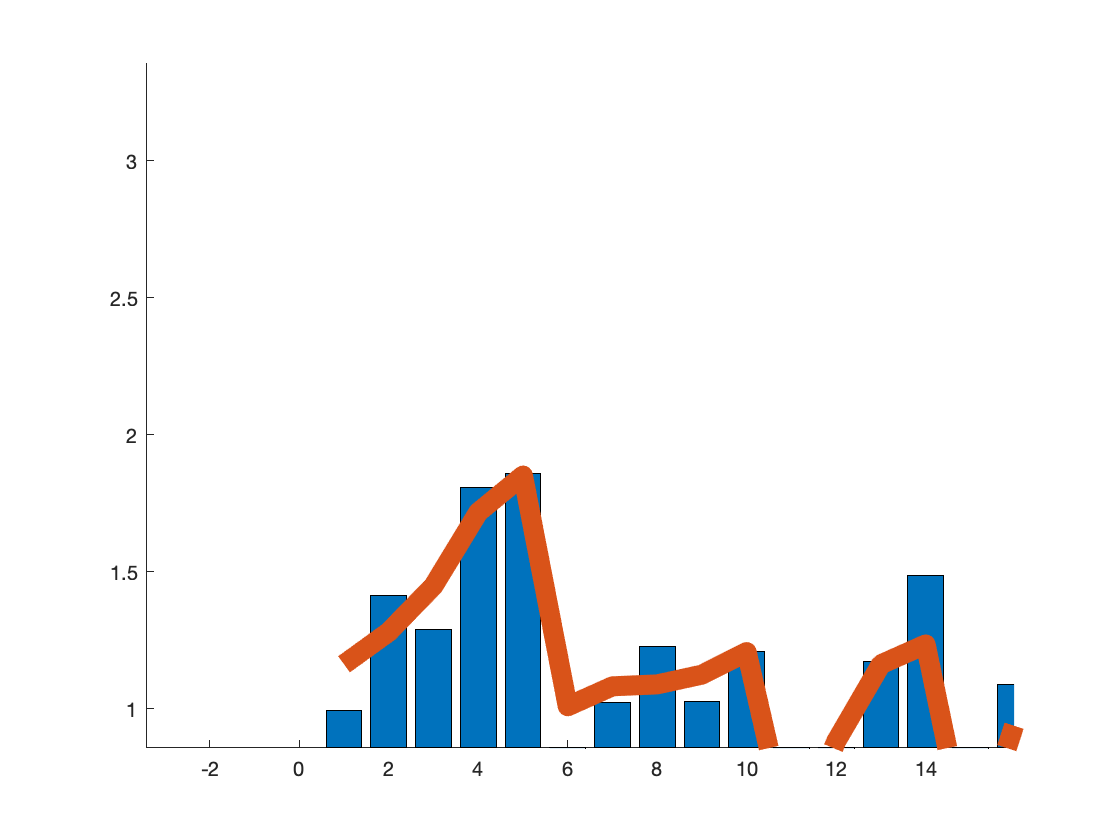

    0.0220



figure; hold on;bar(BOLD_tar); plot(BOLD_hat, "LineWidth", 10); disp(double(mean((BOLD_tar - BOLD_hat).^2)))

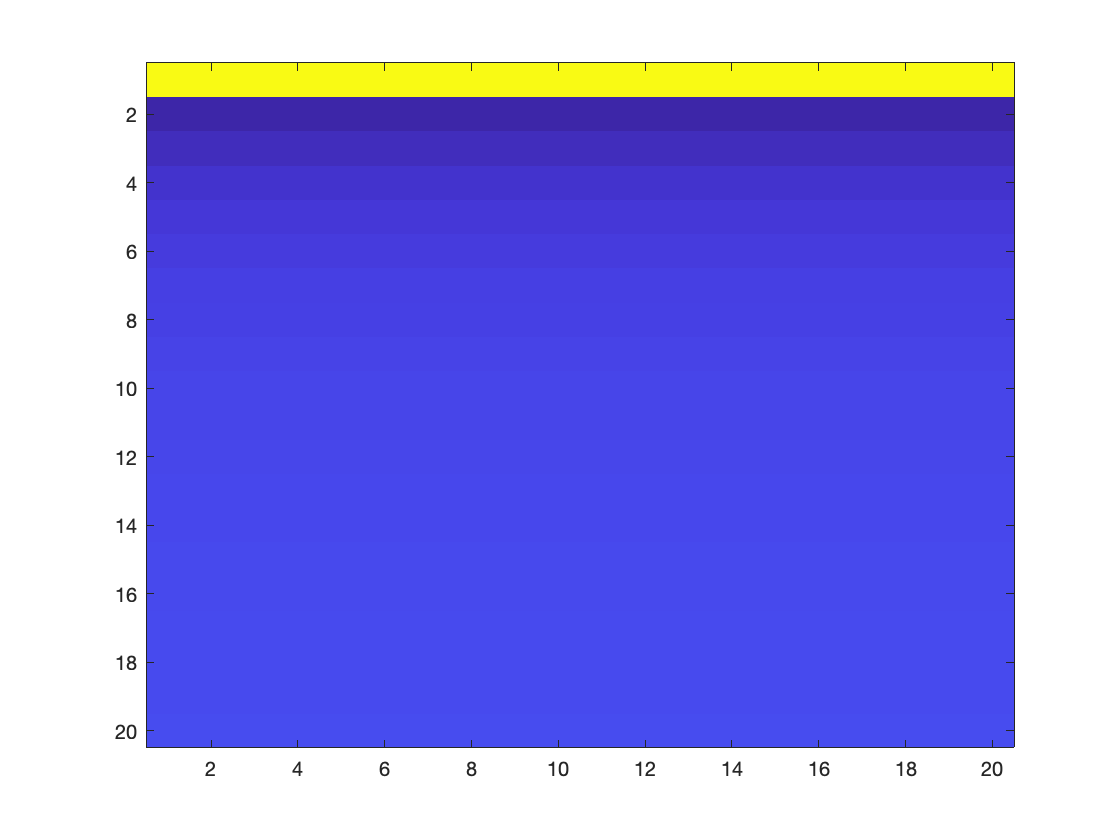

figure; imagesc(mse_land)

param = [0.1, .2, .2];
BOLD_hat = model.forward(model, E, Z, param);
mse = double(mean((BOLD_tar - BOLD_hat).^2))

mse = 1.2254

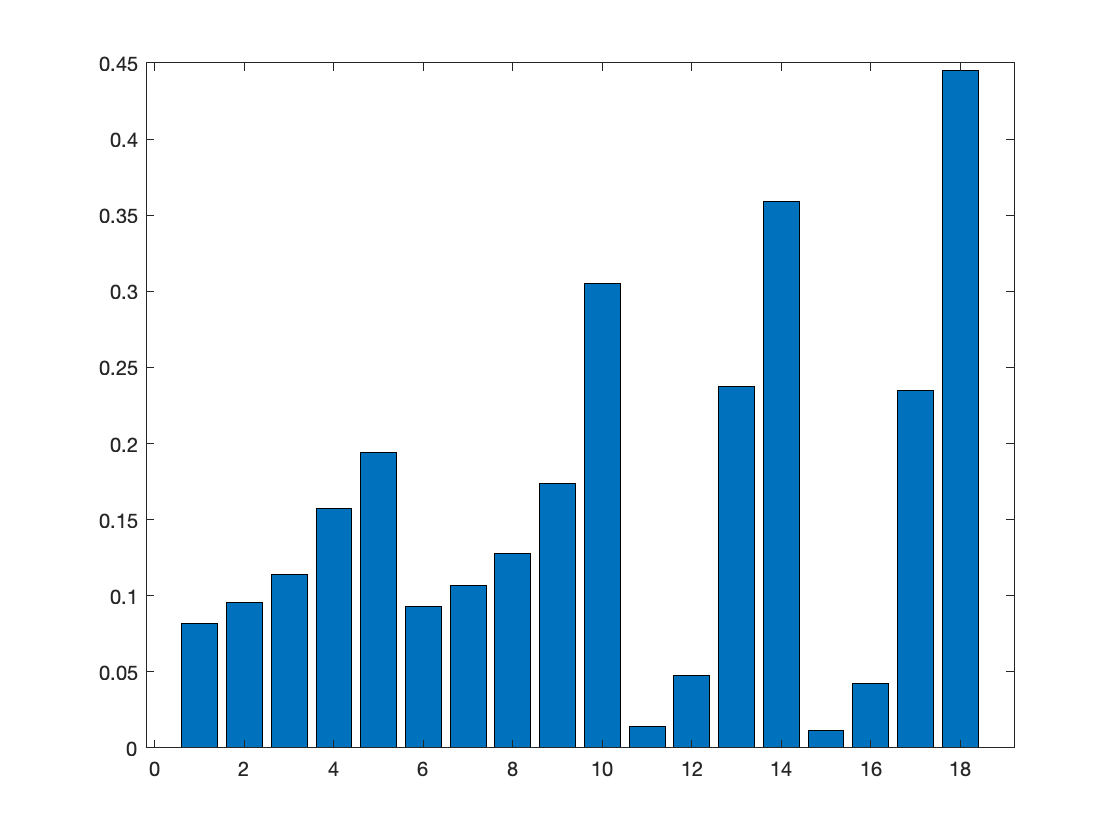

bar(BOLD_hat)

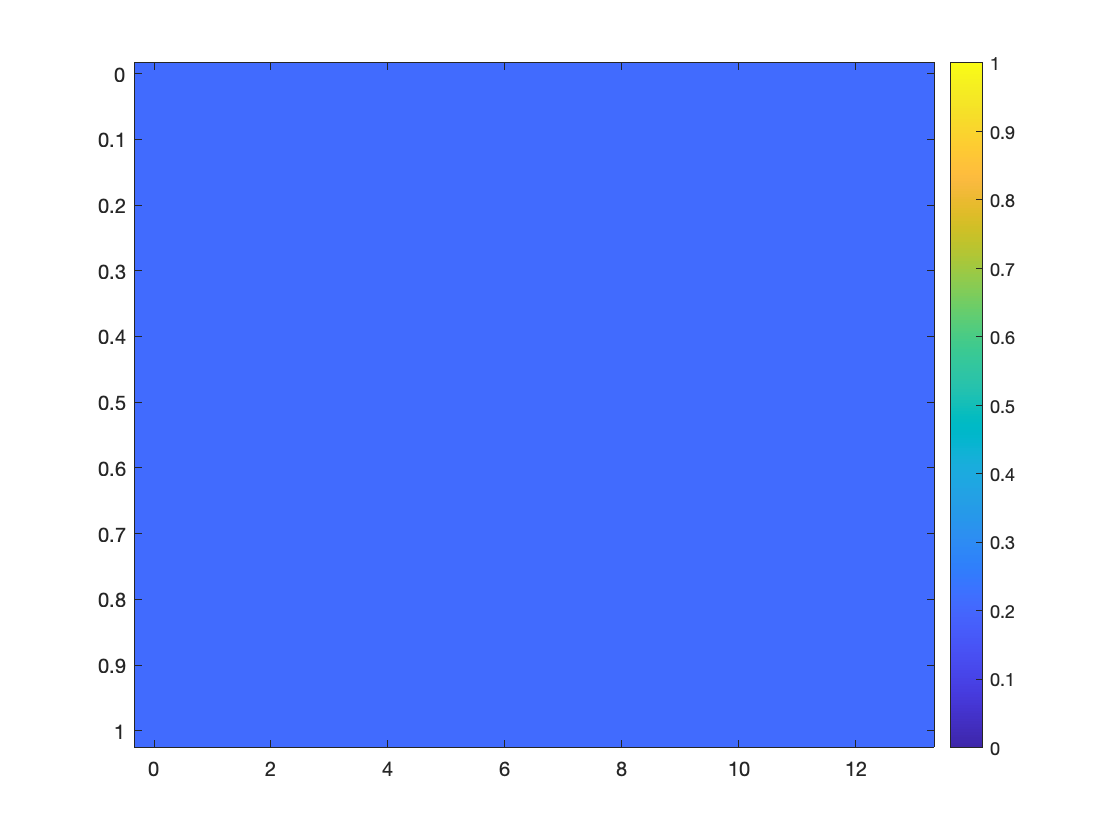

% visualize 
mse_land(imag(mse_land) ~= 0) = inf;
figure();
imagesc(nLst, wLst, mse_land,[0, 1]);
colorbar;

min(mse_land(:))

ans = 0.2110